clear
clf
load("Experiment 1\Vin.mat")
load("Experiment 1\Iout_ch2.mat")
load("Experiment 1\Iout_ch1.mat")
Ve=0;
Ie=-Iout_ch2;
Ib=Iout_ch1;
Ic=Ie-abs(Ib);
%line of best fit
[first, last, mmax, bmax, Nmax]=linefit(Vin,log(Ic), 5e-6);
 Is = exp(bmax)

Is = 6.1754e-15

 Ut = 1/mmax

Ut = 0.0263

 Ic_theory=Is*exp((Vin-Ve)/Ut);
 [first, last, mmax, bmax, Nmax]=linefit(Vin, log(Ib), 1e-5);
B =Is/exp(bmax)

B = 162.4044

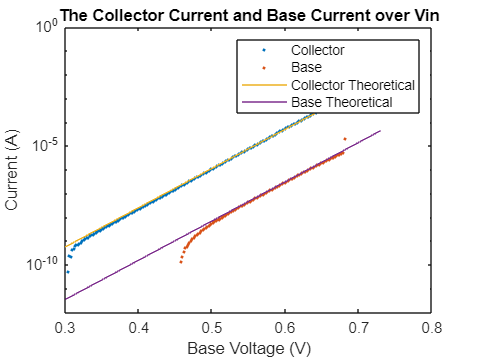

 Ib_theory=Is/B*exp((Vin-Ve)/Ut);
semilogy(Vin,Ic,'.',Vin,Ib,'.',Vin,Ic_theory,Vin,Ib_theory)

title("The Collector Current and Base Current over Vin")
legend('Collector','Base','Collector Theoretical','Base Theoretical')
ylabel("Current (A)")
xlabel("Base Voltage (V)")

clf

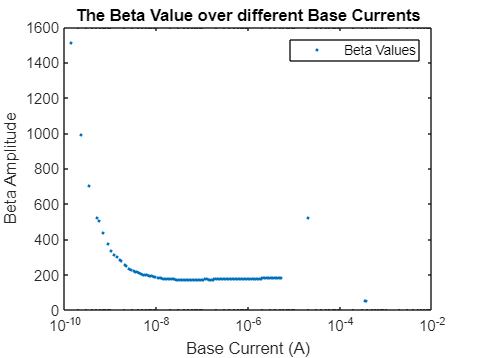

semilogx(Ib,Ic./Ib,'.')
title("The Beta Value over different Base Currents")
legend("Beta Values")
ylabel("Beta Amplitude")
xlabel("Base Current (A)")

clf

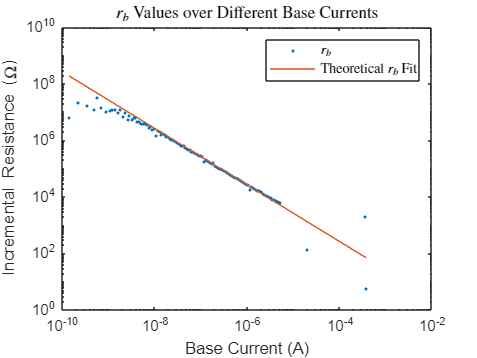

dVbdIb = [0;diff(Vin(:))./diff(Ib(:))];
loglog(Ib,dVbdIb,'.',Ib,Ut./Ib)
title("$r_b$ Values over Different Base Currents","Interpreter","latex")
legend("$r_b$","Theoretical $r_b$ Fit","Interpreter","latex")
ylabel("Incremental Resistance (\Omega)")
xlabel("Base Current (A)")

clf

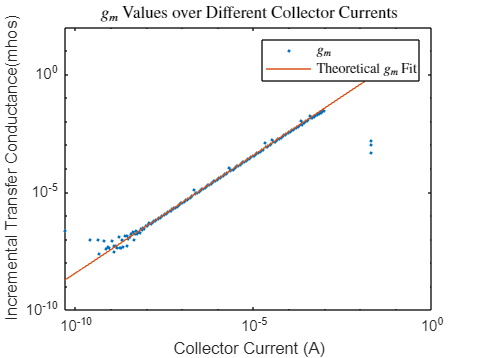

dIcdVb = [0;diff(Ic(:))./diff(Vin(:))];
loglog(Ic,dIcdVb,'.',Ic, Ic/Ut)
title("$g_m$ Values over Different Collector Currents","Interpreter","latex")
legend("$g_m$","Theoretical $g_m$ Fit","Interpreter","latex")
ylabel("Incremental Transfer Conductance(mhos)")
xlabel("Collector Current (A)")